clc
clear all
close all


# ELABORATO SERVOSYSTEMS & ROBOTICS

Link's dimentions expressed in decimeters:

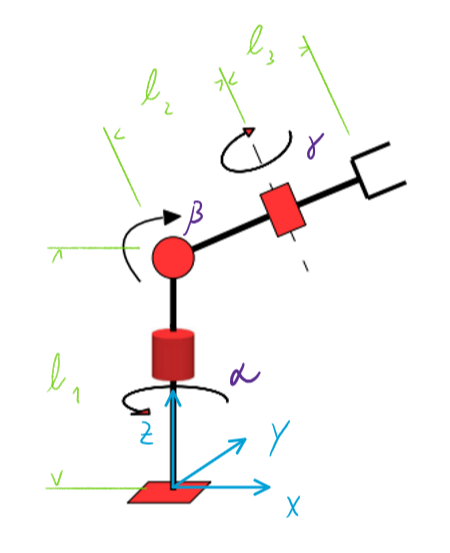

- Length of **Link 1**:

link1 = 12;

Link1 has a **Revolute Joint **that can freely rotate around the $z$ axis. $\alpha =\left\lbrack 0;\;2\pi \right\rbrack \ldotp$

- Length of **Link 2**:

link2 = 7;

Link2 has a **Revolute Joint **that can freely rotate in planes $y\;z$. $\beta =\left\lbrack 0;\;2\pi \right\rbrack$*. *

- Length of **Link 3**:

link3 = 4;

Link3 has a **Revolute Joint **that can freely rotate based on second link. $\gamma =\left\lbrack 0;\;2\pi \right\rbrack$.

L = [link1, link2, link3];    % matrice link

        ** 2.  KINEMATICS & DYNAMICS**:

- Kinematics data:

- Direct kinematic configuration:

Qi = [0.5337, -0.3913, -0.2426]';
Qf = [1.3065, 0.0041, -1.9709]';

- Direct kinematic angular Speed Matrixes:

Lry= [0, 0, 1, 0;
      0, 0, 0, 0;
     -1, 0, 0, 0;
      0, 0, 0, 0];

Lrz=[0,-1, 0, 0;
     1, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0];

***DYNAMICS DATA***

- External forces (N):

Fx = 0;
Fy = 0;
Fz = 0;

F_ext = [0,  0,  0,  Fx;
         0,  0,  0,  Fy;
         0,  0,  0,  Fz;
        -Fx,-Fy,-Fz, 0];

Hg = zeros(4); 
Hg(3,4) = -9.81;

- Centri di gravità (dm):

g1 = 6;
g2 = 3.5;
g3 = 2;

G = [g1 g2 g3 1];

- Masse (kg) e inerzie:

% pesi presi da simulazione Solidworks di un robot in alluminio [kg]

m1 = 102;
m2 = 33;
m3 = 8.5;


% matrici inerzia prese da simulazione Solidworks di un robot in alluminio [kg*dm]

Jx = [5.1 0.9 0.1];
Jy = [124.6 14 1.2];
Jz = [124.6 14 1.2];

Jg = [124.6 14 1.2];
Jxy = 0; Jxz = 0; Jyz = 0;

- Martrici Momenti di inerzia:

J1 = [Jx(1) Jxy Jxz;
      Jxy Jy(1) Jyz;
      Jxz Jyz Jz(1)];

J2 = [Jx(2) Jxy Jxz;
      Jxy Jy(2) Jyz;
      Jxz Jyz Jz(2)];

J3 = [Jx(3) Jxy Jxz;
      Jxy Jy(3) Jyz;
      Jxz Jyz Jz(3)];
  

- Shift Matrixes:

M1_1 = [1, 0, 0, -(link1-g1);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

M2_2 = [1, 0, 0, -(link2-g2);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

M3_3 = [1, 0, 0, -(link3-g3);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

- Pseudo insertia matrixes:

J1_1 = pseudoInertia(J1,m1);
J11 = M1_1*J1_1*M1_1';

J2_2 = pseudoInertia(J2,m2);
J22 = M2_2*J2_2*M2_2';

J3_3 = pseudoInertia(J3,m3);
J33 = M3_3*J3_3*M3_3';

- Dynamic Evaluation:

J11_0 = [];
J22_0 = [];
J33_0 = [];

FF1 = [];
FF2 = [];
FF3 = [];

F_ext_0 = [];

EK_tot = [];
EP_tot = [];

CC1 = [];
CC2 = [];
CC3 = [];

WW1 = [];
WW2 = [];
WW3 = [];
WW4 = [];
WW_tot = [];



- ***TRAJECTORY PLAN***

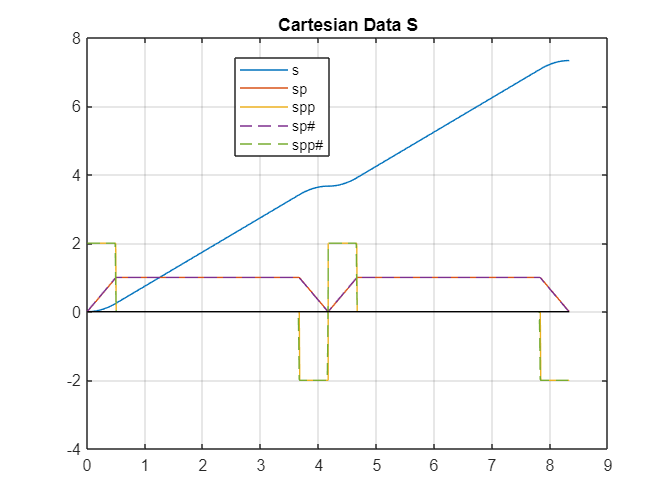


A = [1,-2];
B = [2,-1];
C = [1,0];

D = C;
E = [2,1];
F = [1,2];

[xc1,yc1,r1] = Find_Circ(A,B,C);
[xc2,yc2,r2] = Find_Circ(D,E,F);

xc1 = double(xc1);  xc2 = double(xc2);
yc1 = double(yc1);  yc2 = double(yc2);
r1 = double(r1);    r2 = double(r2);

N = 500;

th1 = linspace(-pi/2-pi/6,pi/2,N);
th2 = linspace(-pi/2,pi/2+pi/6,N);
th_tot = [th1, th2];

l1 = (0-(-pi/6-pi))*r2;
l2 = (pi/6-(-pi))*r1;

L_t = [l1,l2];

x1 = r1*cos(th1) + xc1;
x2 = r2*cos(th2) + xc2;
x_tot = [x1 x2];

y1 = r1*sin(th1) + yc1;
y2 = r2*sin(th2) + yc2;
y_tot = [y1 y2];

z_tot = zeros(1,2*N);

S = [x_tot;y_tot;z_tot];


alpha = -pi/4;
Tt = [5,0,12];
Ttva = [0,0,0];

for i = 1:2*N
    
    ss(i) = sqrt(S(1,i)^2 + S(2,i)^2 + S(3,i)^2);
    
end

% figure 
% hold on
% plot(x_tot,y_tot,"-","LineWidth",2)
% axis equal
% pbaspect([20 20 20])
% grid on
% hold off

% dati cinematici robot
n = 2;
A = 2; D = 2; L_t = L_t;

Vmax = 1; Vi = 0; Vf = 0;
Vt = [Vmax, Vmax];
Vn = [Vi, 0, Vf];


[s,sp,spp,tt] = LookAhead_AAA(n,N,L_t,ss,Vt,Vn,A,D);
s = s - s(1);
T = tt(end) - tt(1);
dT = tt(2) - tt(1);
Plot_Single_Graph_Dir_Kinematics_AAA(s,sp,spp,tt,dT);


%% vecchio
% ho la traiettoria S
x = zeros(1,2*N);
y = zeros(1,2*N);
z = zeros(1,2*N);
Theta1 = [];
Theta2 = [];

for i = 1:length(s)
   
    if i <= N
        theta1 = th1(1) + s(i)/r1;
        Theta1 = [Theta1 theta1];
        x(i) = xc1 + r1*cos(theta1);
        y(i) = yc1 + r1*sin(theta1);
    else 
        theta2 = th2(1) + (s(i)-s(N))/r2;
        Theta2 = [Theta2 theta2];
        x(i) = xc2 + r1*cos(theta2);
        y(i) = yc2 + r1*sin(theta2);
    end
   
    
end

P = [x;y;z];
S1 = [];

% calcoli valori per singoli assi
% velocità ------------GIUSTI
TH_TOT = [Theta1 Theta2];

vx = -sp.*sin(TH_TOT);
vy = sp.*cos(TH_TOT);
vz = sp.*0;
Sp = [vx;vy;vz];
Sp1 = [];

% accelerazione ------------GIUSTI
sppc = -(sp.^2)./r1;
spp_tot = sqrt((spp.^2) + (sppc.^2));
atx = -spp.*sin(TH_TOT);    acx = sppc.*cos(TH_TOT);
aty = spp.*cos(TH_TOT);    acy = sppc.*sin(TH_TOT);
ax = atx + acx;
ay = aty + acy;
az = spp.*0;
Spp = [ax;ay;az];
Spp1 = [];

tt = [tt(1:N) tt(N+2:end)];
P = [P(:,1:N) P(:,N+2:end)];
Sp = [Sp(:,1:N) Sp(:,N+2:end)];
Spp = [Spp(:,1:N) Spp(:,N+2:end)];

%Plot_Graphs_Dir_Kinematics_AAA(P,Sp,Spp,tt,dT)

Q = [];
Qs = [];
Qp = [];
Qpp = [];
% calcolo traiettoria

***DIRECT KINEMATICS:***

for i = 1:length(tt)  
    
    s1 = rototrasla_Punto(P(:,i),alpha,Tt,'y');
    S1 = [S1 s1];
    q = Inverse_Kinematics_AAA(s1,L,2)';
    Q = [Q q];
    sp1 = rototrasla_Punto(Sp(:,i),alpha,Ttva,'y');
    Sp1 = [Sp1 sp1];
    spp1 = rototrasla_Punto(Spp(:,i),alpha,Ttva,'y');
    Spp1 = [Spp1 spp1];
    
    j = Jac_AAA(q,L);
    sp_inv = sp1;
    jinv = (j^-1);
    qp = jinv*sp1(1:3);
    Qp = [Qp qp];
    
    
    jp = JacP_AAA(q,qp,L);
    qpp = jinv*(spp1(1:3)-jp*qp);
    Qpp = [Qpp qpp];
    
    [ss,M01,M12,M23] = Rotation_Matrixes_AAA(q,L); 

    M02 = M01*M12;
    M03 = M02*M23;
    
    % In generale Hij_k significa accelerazione di (j) rispetto ad (i) vista dal sistema 
    % (k)  (in maniera analoga anche per le velocità)

- Speed Evaluation:

    w01_0 = Lrz*qp(1);      % speed in 0-1 seen by the referece system 0
    w12_0 = M01*Lry*qp(2)*inv(M01);     % speed in 1-2 seen by the referece system 0
    w23_0 = M02*Lrz*qp(3)*inv(M02);     % speed in 2-3 seen by the referece system 0
    
    w02_0 = w01_0 + w12_0;      % speed in 0-2 seen by the referece system 0 (sum of speed 0-1 % 1-2)
    w03_0 = w02_0 + w23_0;      % speed in 0-3 (gripper total speed) seen by the referece system 0 (sum of speed 0-2 % 2-3)

- Acceleration Evaluation:

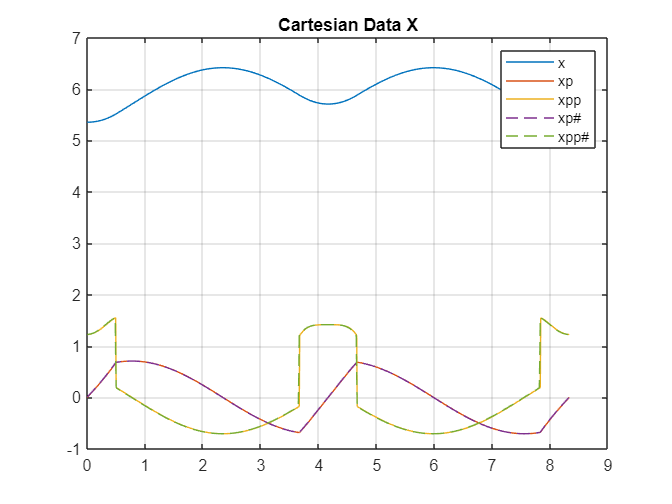

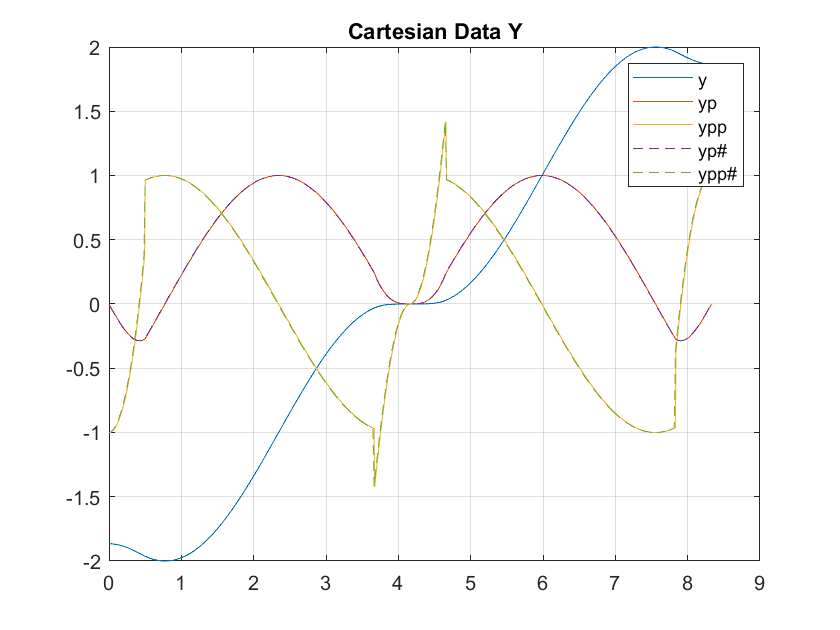

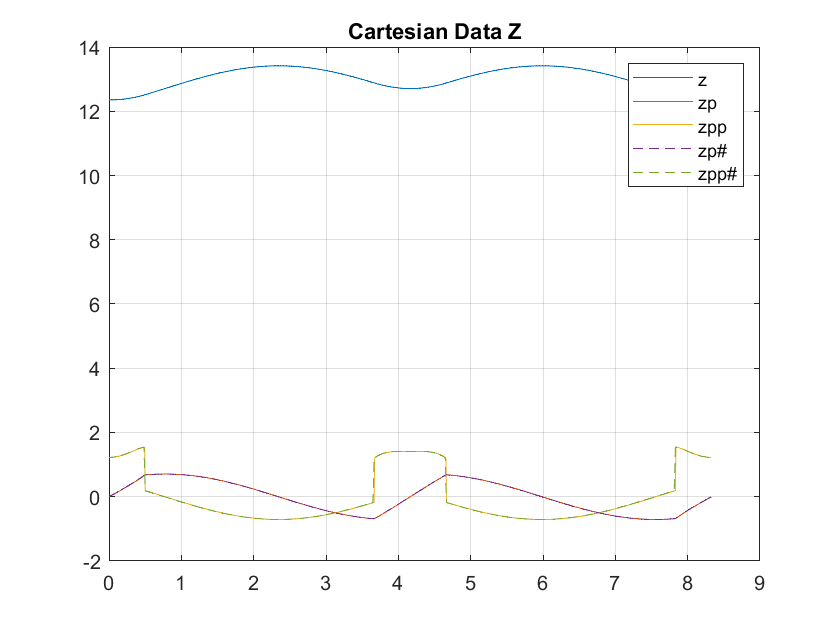

    h01_0 = (Lrz*qpp(1) + Lrz^2*qp(1)^2);       % acceleration in 0-1 seen by the referece system 0

    h12_0 = M01*(Lry*qpp(2) + Lry^2*qp(2)^2)*inv(M01);      % acceleration in 1-2 seen by the referece system 0
    h23_0 = M02*(Lrz*qpp(3) + Lrz^2*qp(3)^2)*inv(M02);      % acceleration in 2-3 seen by the referece system 0
    
    h02_0 = h01_0 + h12_0 + 2*w01_0*w12_0;      % acc in 0-2 seen by the referece system 0 (sum of acc 0-1 % 1-2 and coriolis between them)
    h03_0 = h02_0 + h23_0 + 2*w02_0*w23_0;      % acc in 0-3 seen by the referece system 0 (sum of acc 0-2 % 2-3 and coriolis between them)

***DYNAMICS EVALUATION:***

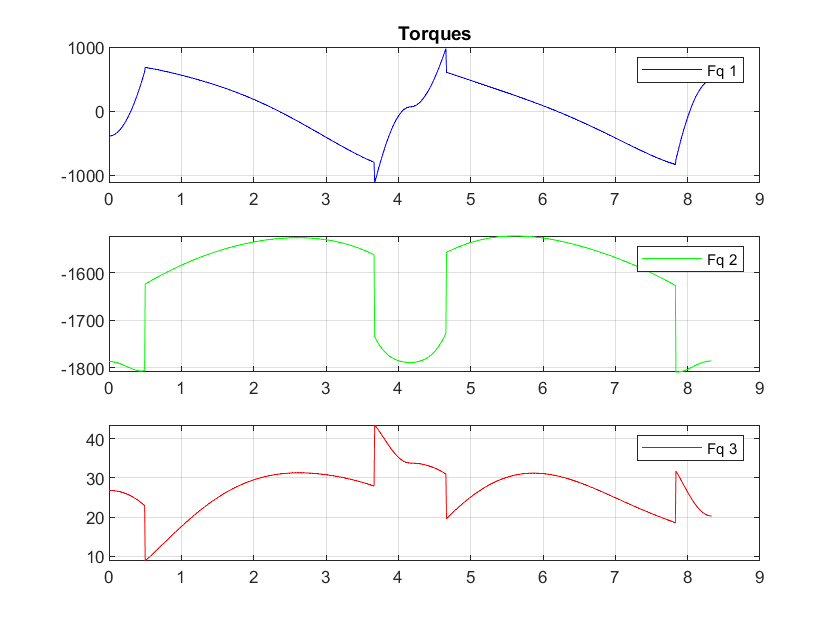

    j11_0 = M01*J11*M01';
    j22_0 = M02*J22*M02';
    j33_0 = M03*J33*M03';
    
    J11_0 = [J11_0 j11_0];
    J22_0 = [J22_0 j22_0];
    J33_0 = [J33_0 j33_0];
    
    
    ff1i = -(h01_0*j11_0 - j11_0*h01_0');
    ff2i = -(h02_0*j22_0 - j22_0*h02_0');
    ff3i = -(h03_0*j33_0 - j33_0*h03_0');
    
    ff1g = Hg*j11_0 - j11_0*Hg';

    ff2g = Hg*j22_0 - j22_0*Hg';
    ff3g = Hg*j33_0 - j33_0*Hg';
    
    
    M0a = eye(4,4);
    M0a(:,4) = M03(:,4); 
    fext_0 = M0a*F_ext*M0a'; 

    ff3 = ff3i+ff3g+fext_0;
    ff2 = ff2i+ff2g+ff3;
    ff1 = ff1i+ff1g+ff2; 
    
    FF1 = [FF1 ff1];
    FF2 = [FF2 ff2];
    FF3 = [FF3 ff3];
    
    F_ext_0 = [F_ext_0 fext_0];

- Kinematic Energy:

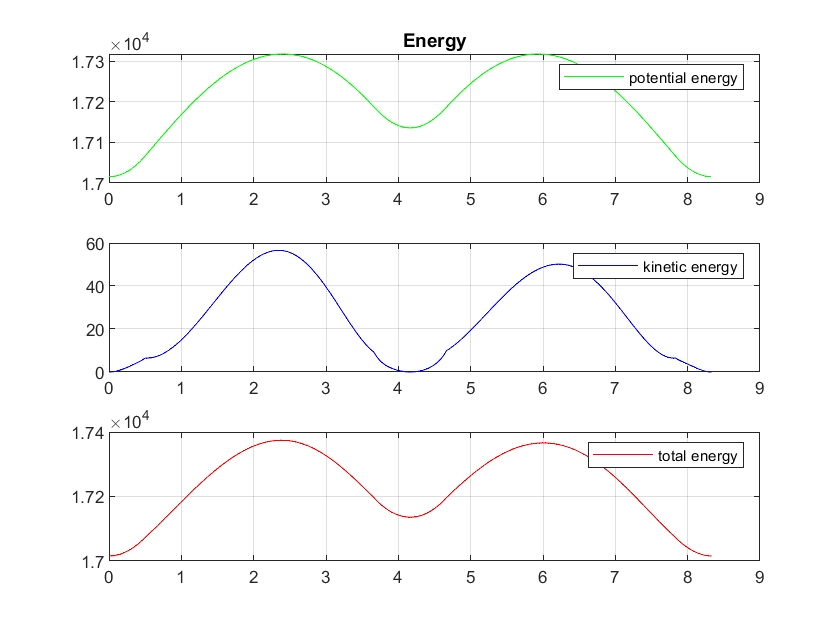

    ek1 = trace(1/2*w01_0*j11_0*w01_0');
    ek2 = trace(1/2*w02_0*j22_0*w02_0');
    ek3 = trace(1/2*w03_0*j33_0*w03_0');

    
    ek_tot = ek1 + ek2 + ek3;
    
    EK_tot = [EK_tot ek_tot];

- Potential Energy:

    ep1 = -trace(Hg*j11_0);
    ep2 = -trace(Hg*j22_0);
    ep3 = -trace(Hg*j33_0);

    ep_tot = ep1 + ep2 + ep3;
    
    EP_tot = [EP_tot ep_tot];

- Torque of Forces:

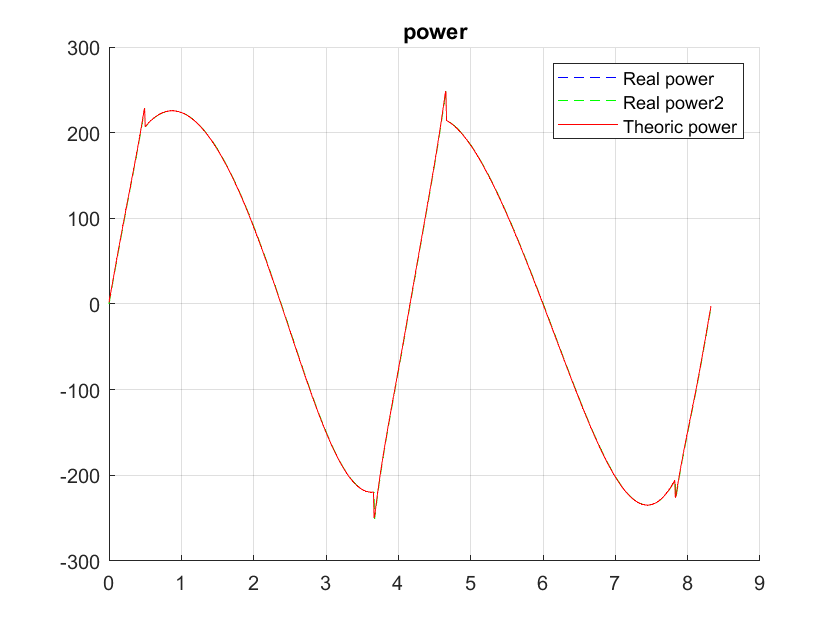

    L12_0 = M01*Lry*inv(M01); 

    L23_0 = M02*Lrz*inv(M02); 
    
    cc1 = -PseDot(ff1,Lrz);
    cc2 = -PseDot(ff2,L12_0); 
    cc3 = -PseDot(ff3,L23_0); 
    
    CC1 = [CC1 cc1];
    CC2 = [CC2 cc2];
    CC3 = [CC3 cc3];

- Power of Forces:

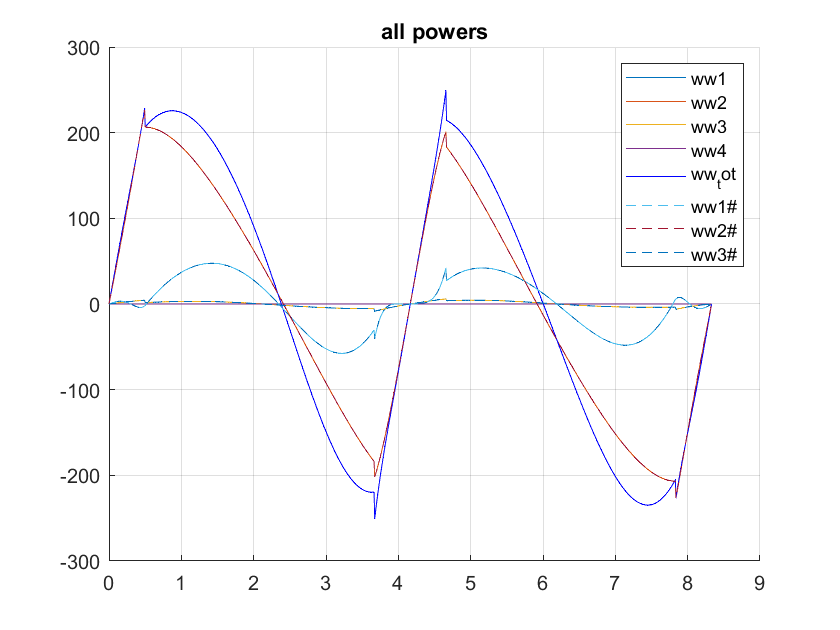

    ww1 = -PseDot(ff1,w01_0);
    ww2 = -PseDot(ff2,w12_0);
    ww3 = -PseDot(ff3,w23_0);
    ww4 = PseDot(fext_0,w03_0);
    ww_tot = ww1+ww2+ww3+ww4;
    
    www1(i) = cc1*qp(1); 
    www2(i) = cc2*qp(2); 
    www3(i) = cc3*qp(3); 
    www_tot2(i) = www1(i)+www2(i)+www3(i)+ww4; % VERIFICA CALCOLO DI PSEDOT
    

    WW1 = [WW1 ww1];
    WW2 = [WW2 ww2];
    WW3 = [WW3 ww3];
    WW4 = [WW4 ww4];
    WW_tot = [WW_tot ww_tot];


end


- Total Energy:

E_tot = EK_tot + EP_tot;

- Total theoretical diff of power: for debug

P_tot = theorethicalDiff(E_tot,dT);

** 2.1 PLOT**:

- Plot configurations:

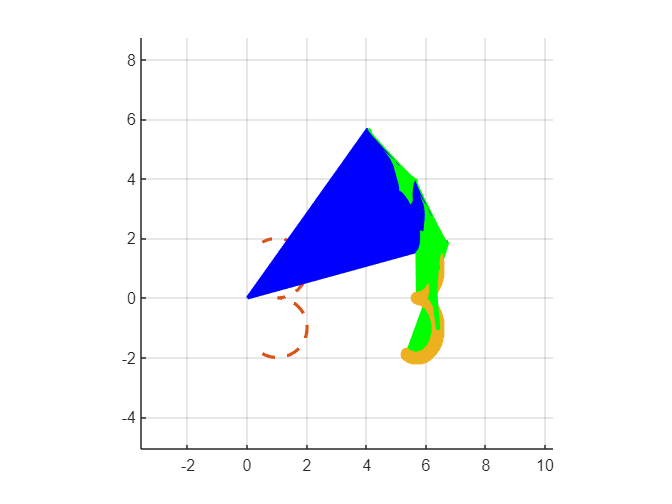

%% plot configurations

% Dati da cinematica diretta:
%Plot_Trajectory_AAA(Qi,Qf,L,S1(1,:),S1(2,:),S1(3,:),n,"Giunti");

% Dati da cinematica inversa:

%Plot_Trajectory_AAA(Q_inv(:,1),Q_inv(:,end),L,x,y,z,n,"Lineare");

- Plot graph of data x,y,z position speed and acceleration direct kinematics:

Plot_Graphs_Dir_Kinematics_AAA(S1,Sp1,Spp1,tt,dT)

- Plot Coppie:

h = figure;
set(h,'name','torques')
subplot(3,1,1)
plot(tt,CC1,'b')
legend("Fq 1")
grid on
title("Torques")

subplot(3,1,2)
plot(tt,CC2,'g')
legend("Fq 2")
grid on

subplot(3,1,3)
plot(tt,CC3,'r')
legend("Fq 3")
grid on

- Plot Energia:

h = figure;
set(h,'name','energy') 

subplot(3,1,1)
plot(tt,EP_tot,'g')
legend("potential energy")
grid on
title("Energy")

subplot(3,1,2)
plot(tt,EK_tot,'b')
legend("kinetic energy")
grid on

subplot(3,1,3)
plot(tt,E_tot,'r')
legend("total energy")
grid on

- Plot Potenze reali e teoriche:

h = figure;
set(h,'name','power') 
hold on
grid on
plot(tt,WW_tot,'b--')
plot(tt,www_tot2,'g--')

plot(tt(1:length(P_tot)),P_tot,'r')
legend("Real power", "Real power2", "Theoric power")
title("power")

- Plot tutte le potenze:

h = figure;
set(h,'name','all power') 

hold on
grid on

plot(tt,WW1)
plot(tt,WW2)
plot(tt,WW3)
plot(tt,WW4)
plot(tt,WW_tot,'b')

plot(tt,www1,'--')
plot(tt,www2,'--')
plot(tt,www3,'--')

legend("ww1","ww2","ww3","ww4","ww_tot","ww1#","ww2#","ww3#")
title("all powers")



% figure
% Plot_Trajectory_animation_AAA(Q,S1,L,length(tt),T,"Cartesiano")

% plot configurazioni assunte
figure
hold on
% % 
for i = 1:length(tt)
   
    Plot_AAA(Q(:,i),L,"xyz");
    
end

plot3(x_tot,y_tot,z_tot,"--","LineWidth",2)
plot3(S1(1,:),S1(2,:),S1(3,:),"-o","LineWidth",2)

axis equal
pbaspect([20 20 20])
grid on
hold off


save dati2 Q Qp Qpp S1 Sp1 Spp1 CC1 CC2 CC3 EP_tot EK_tot E_tot WW_tot P_tot tt
